# 2 DOF Cell Model in plane strain

## Data

% 
clearvars; close all; clc;
set_env;

addpath("2DOF\");
addpath("1DOF\");
load('cell_2dof.mat')
load('cell_2dof_pstrain.mat')
load('1DOF\cell_1dof_pstrain.mat')
load('1DOF\res_1dof_pstrain.mat')

% Data --------------------------------------------------------------
epsilon1_max = 0.05;

% Symbolic variables ------------------------------------------------
% Physical properties
syms nu Y_p epsilon_p epsilon_f EBD_p EBD_f real positive

% Geometry of the capacitor
syms x l_0 l_c w_0 tp_0 xi xi_0 tf_0 dt_f dtf real positive
% t_f(x) armature distance at a certain xsi

% Physical quantities
syms V F

syms epsilon_1(x) epsilon_2(x) epsilon_3(x) sigma_1(x)

## Equations

% Equations ---------------------------------------------------------
makeassumptions
% Geometry ------------------------------
dt_f(x) = simplify(solve((x/2 - tf_0 / 2) / (l_0 - l_c) == (dtf / 2) / (l_0 - l_c - (xi - xi_0)), dtf), 25)

$$dt\_f(x) = -\frac{\left({\mathrm{tf}}_{0}-x\right)\,\left(l_{0}-l_{c}-\xi +\xi_{0}\right)}{l_{0}-l_{c}}$$

t_f(x) = tf_0 + dt_f;
% limit(t_f(x), l_c, l_0)

w = pstrain_2dof.w

$$w = w_{0}$$

t_p = pstrain_2dof.t_p

$$t\_p = {\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)$$

l_a = pstrain_2dof.l_a

$$l\_a = l_{0}-l_{c}+\frac{{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}-8\,l_{c}}$$

A1 = pstrain_2dof.A1

$$A1 = l_{c}\,w_{0}$$

A2 = pstrain_2dof.A2

$$A2 = w_{0}\,\left(l_{0}-l_{c}+\frac{{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}-8\,l_{c}}\right)$$

C1_str = pstrain_2dof.C1

$$C1\_str = \frac{1}{\frac{{\mathrm{tf}}_{0}}{\epsilon_{f}\,l_{c}\,w_{0}}+\frac{2\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)}{\epsilon_{p}\,l_{c}\,w_{0}}}$$

C2_str = pstrain_2dof.C2

$$C2\_str = \frac{\log\left(-\left(\epsilon_{p}\,{\mathrm{tf}}_{0}+2\,\epsilon_{f}\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)\right)\,\left(l_{0}-l_{c}\right)-\epsilon_{p}\,l_{c}\,\left({\mathrm{tf}}_{0}-x\right)\right)\,\left(\epsilon_{f}\,l_{0}\,w_{0}-\epsilon_{f}\,l_{c}\,w_{0}+\epsilon_{f}\,l_{0}\,w_{0}\,\epsilon_{1}\left(x\right)-\epsilon_{f}\,l_{c}\,w_{0}\,\epsilon_{1}\left(x\right)\right)}{{\mathrm{tf}}_{0}-x}-\frac{\log\left(\epsilon_{p}\,\left(l_{0}-l_{c}\right)\,\left({\mathrm{tf}}_{0}-x\right)-\left(\epsilon_{p}\,{\mathrm{tf}}_{0}+2\,\epsilon_{f}\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)\right)\,\left(l_{0}-l_{c}\right)\right)\,\left(\epsilon_{f}\,l_{0}\,w_{0}-\epsilon_{f}\,l_{c}\,w_{0}+\epsilon_{f}\,l_{0}\,w_{0}\,\epsilon_{1}\left(x\right)-\epsilon_{f}\,l_{c}\,w_{0}\,\epsilon_{1}\left(x\right)\right)}{{\mathrm{tf}}_{0}-x}$$

Vol_0 = pstrain_2dof.Vol_0                 

$$Vol\_0 = 2\,l_{0}\,{\mathrm{tp}}_{0}\,w_{0}$$


pstrain = sstrain2(pstrain_2dof, "PSTRAIN");
Vol = pstrain.Vol

$$Vol = w_{0}\,\left(l_{c}\,{\mathrm{tf}}_{0}+\frac{\left({\mathrm{tf}}_{0}+x\right)\,\left(l_{0}-l_{c}\right)}{2}+x\,\xi_{0}\right)+2\,{\mathrm{tp}}_{0}\,w_{0}\,\left(l_{0}+\frac{{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}-8\,l_{c}}\right)$$

C1 = pstrain.C1

$$C1 = \frac{1}{\frac{{\mathrm{tf}}_{0}}{\epsilon_{f}\,l_{c}\,w_{0}}+\frac{2\,{\mathrm{tp}}_{0}\,\left(\frac{\nu \,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}\,\left(l_{0}-l_{c}\right)\,\left(\nu -1\right)}+1\right)}{\epsilon_{p}\,l_{c}\,w_{0}}}$$

C2 = pstrain.C2

$$C2 = \frac{\log\left(-\left(l_{0}-l_{c}\right)\,\left(\epsilon_{p}\,{\mathrm{tf}}_{0}+2\,\epsilon_{f}\,{\mathrm{tp}}_{0}\,\left(\frac{\nu \,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}\,\left(l_{0}-l_{c}\right)\,\left(\nu -1\right)}+1\right)\right)-\epsilon_{p}\,l_{c}\,\left({\mathrm{tf}}_{0}-x\right)\right)\,\left(\epsilon_{f}\,l_{0}\,w_{0}-\epsilon_{f}\,l_{c}\,w_{0}+\frac{\epsilon_{f}\,w_{0}\,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,\left(l_{0}-l_{c}\right)}-\frac{\epsilon_{f}\,l_{c}\,w_{0}\,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}\,\left(l_{0}-l_{c}\right)}\right)}{{\mathrm{tf}}_{0}-x}-\frac{\log\left(\epsilon_{p}\,\left(l_{0}-l_{c}\right)\,\left({\mathrm{tf}}_{0}-x\right)-\left(l_{0}-l_{c}\right)\,\left(\epsilon_{p}\,{\mathrm{tf}}_{0}+2\,\epsilon_{f}\,{\mathrm{tp}}_{0}\,\left(\frac{\nu \,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}\,\left(l_{0}-l_{c}\right)\,\left(\nu -1\right)}+1\right)\right)\right)\,\left(\epsilon_{f}\,l_{0}\,w_{0}-\epsilon_{f}\,l_{c}\,w_{0}+\frac{\epsilon_{f}\,w_{0}\,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,\left(l_{0}-l_{c}\right)}-\frac{\epsilon_{f}\,l_{c}\,w_{0}\,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}\,\left(l_{0}-l_{c}\right)}\right)}{{\mathrm{tf}}_{0}-x}$$

pureUel = pstrain.pure_Uel

$$pureUel(x) = -\frac{Y_{p}\,{\mathrm{tp}}_{0}\,w_{0}\,\left(\frac{\nu \,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}\,\left(l_{0}-l_{c}\right)\,\left(\nu -1\right)}+1\right)\,\left(l_{0}+\frac{{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}-8\,l_{c}}\right)\,{\left({\mathrm{tf}}_{0}-x\right)}^{4}}{64\,{l_{0}}^{2}\,\left(\nu^{2}-1\right)\,{\left(l_{0}-l_{c}\right)}^{2}}$$


% pstrain.A1 = l_c * pstrain.w; 
% C1 = (1 / pstrain.Cf1 + 2 / (pstrain.A1 * epsilon_p / pstrain.t_p))^(-1)
% makeassumptions
% fprintf("C1 as x -> tf_0 \n")
% simplify(limit(C1, x, tf_0))
% fprintf("C1 as l_c -> l_0 \n")
% simplify(limit(C1, l_c, l_0))
% fprintf("C1 as l_c -> 0 \n")
% simplify(limit(C1, l_c, 0))
% 
% C2 = simplify(pstrain.C2)
% makeassumptions
% fprintf("C2 as x -> tf_0 \n")
% simplify(limit(sstrain2(C2), x, tf_0))
% fprintf("C2 as l_c -> l_0 \n")
% simplify(limit(sstrain2(C2), l_c, l_0))
% fprintf("C2 as l_c -> l_0, x -> tf_0 \n")
% simplify(limit(ans, x, tf_0))
% fprintf("C2 as l_c -> 0 \n")
% simplify(limit(sstrain2(C2) , l_c, 0))
% fprintf("C1 1 DOF\n")
% res_1dof_pstrain.C

% myfig(1, "C 1DOF - $C_2$ 2DOF with $l_c$ = 0"); hold on; grid on;
% fplot(x,sdata2(simplify(limit(sstrain2(C2) , l_c, 0))), [double(sdata2(tf_0)) , 10e-3], 'LineWidth', 1.5, 'DisplayName', "$C_2$ 2DOF")
% fplot(x,sdata2(res_1dof_pstrain.C), [double(sdata2(tf_0)) , 10e-3], '--', 'LineWidth', 1.5, 'DisplayName', "C 1DOF")
% legend("Location","northeast")
% title("C 1DOF - $C_2$ 2DOF with $l_c$ = 0")
% xlabel("x [m]")
% ylabel("C(x) [F]")

% Range limit
x_min = sdata2(tf_0)

$$x\_min = 0.00001$$

x_max = sdata2(rhs(isolate(sstrain2(epsilon_1(x)) == epsilon1_max, x)))

$$x\_max = 0.031622776601683793319988935444327\,\sqrt{2}\,\sqrt{5}\,\sqrt{0.025-l_{c}}+0.00001$$

## Capacitance

% Total capacitance +++++++++++++++++++++++++++++++++++++++++++++++++
C = C1

$$C = \frac{1}{\frac{{\mathrm{tf}}_{0}}{\epsilon_{f}\,l_{c}\,w_{0}}+\frac{2\,{\mathrm{tp}}_{0}\,\left(\frac{\nu \,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}\,\left(l_{0}-l_{c}\right)\,\left(\nu -1\right)}+1\right)}{\epsilon_{p}\,l_{c}\,w_{0}}}$$


% Min capacitance
Cmin = vpa(sdata2(limit(C, x, x_max)),4);

% Max capacitance
Cmax = vpa(sdata2(limit(C, x, tf_0)),4);


## Equations

eq_diffx = diff(pureUel, x) - V^2 /2 * diff(C1, x) == F;
eq_difflc = diff(pureUel,l_c) - V^2 /2 * diff(C1, l_c) == 0;

## Solution

load("2DOF\sol_2DOF_usingC1.mat")
C1_tmp = sdata2(C1);
if ~(isequal(x_range, double(linspace(x_min+1e-8, 10e-3, 100))') && isequal(V_range, [0.1 500:500:6000]) ...
        && isequal(eq_x, sdata2(eq_diffx)) && isequal(eq_lc, sdata2(eq_difflc))) | 1
    x_range = double(linspace(x_min+1e-8, 10e-3, 100))';
    V_range = [0.1 500:500:6000];
    eq_x = sdata2(eq_diffx);
    eq_lc = sdata2(eq_difflc);
    sol_lc = zeros(length(V_range), length(x_range));
    sol_F = zeros(length(V_range), length(x_range));
    sol_C1 = zeros(length(V_range), length(x_range));
    stmp = cell(1, length(x_range));
    tic 
    % eq_lcV = subs(eq_lc, V, V_range);
    parfor i = 1:length(V_range)
        eq_lcV = subs(eq_lc, V, V_range(i));
        stmp = cell(1, length(x_range));
        for j = 1:length(x_range)
            stmp{j} = double(vpasolve(subs(eq_lcV, x, x_range(j))));
        end
        sol_lc(i,:) = max(1e-7, cellfun(@(x) real(x(1)) * (imag(x(1)) <= 1e-7 && x(1) > 0), stmp));
        sol_F(i,:) = max(0, arrayfun(@(x) x, double(lhs(subs(eq_x, {V, l_c, x}, {V_range(i), sol_lc(i,:), x_range'})))));
        sol_C1(i,:) = double(subs(C1_tmp, {V, l_c, x}, {V_range(i), sol_lc(i,:), x_range'}));    
    end
    toc
    save("2DOF\sol_2DOF_usingC1.mat", "x_range")
    save("2DOF\sol_2DOF_usingC1.mat", "V_range", '-append')
    save("2DOF\sol_2DOF_usingC1.mat", "sol_lc", '-append')
    save("2DOF\sol_2DOF_usingC1.mat", "sol_F", '-append')
    save("2DOF\sol_2DOF_usingC1.mat", "sol_C1", '-append')
    save("2DOF\sol_2DOF_usingC1.mat", "eq_x", '-append')
    save("2DOF\sol_2DOF_usingC1.mat", "eq_lc", '-append')
end

Elapsed time is 73.563473 seconds.


% x_range = double(linspace(x_min+1e-8, 10e-3, 100))';
% V_range = [0.1 500:500:6000];


## Zipped length - Capacitance - Force

x_range_ref = double(x_min+1e-8:1e-5:10e-3);
[X,Y] = meshgrid(x_range, V_range);
int_type = 'linear';
int_lc = @(x,V) interp2(X,Y,sol_lc, x, V);
int_F = @(x,V) interp2(X,Y,sol_F, x, V);
int_C1 = @(x,V) interp2(X,Y,sol_C1, x, V);

myfig(1, "")

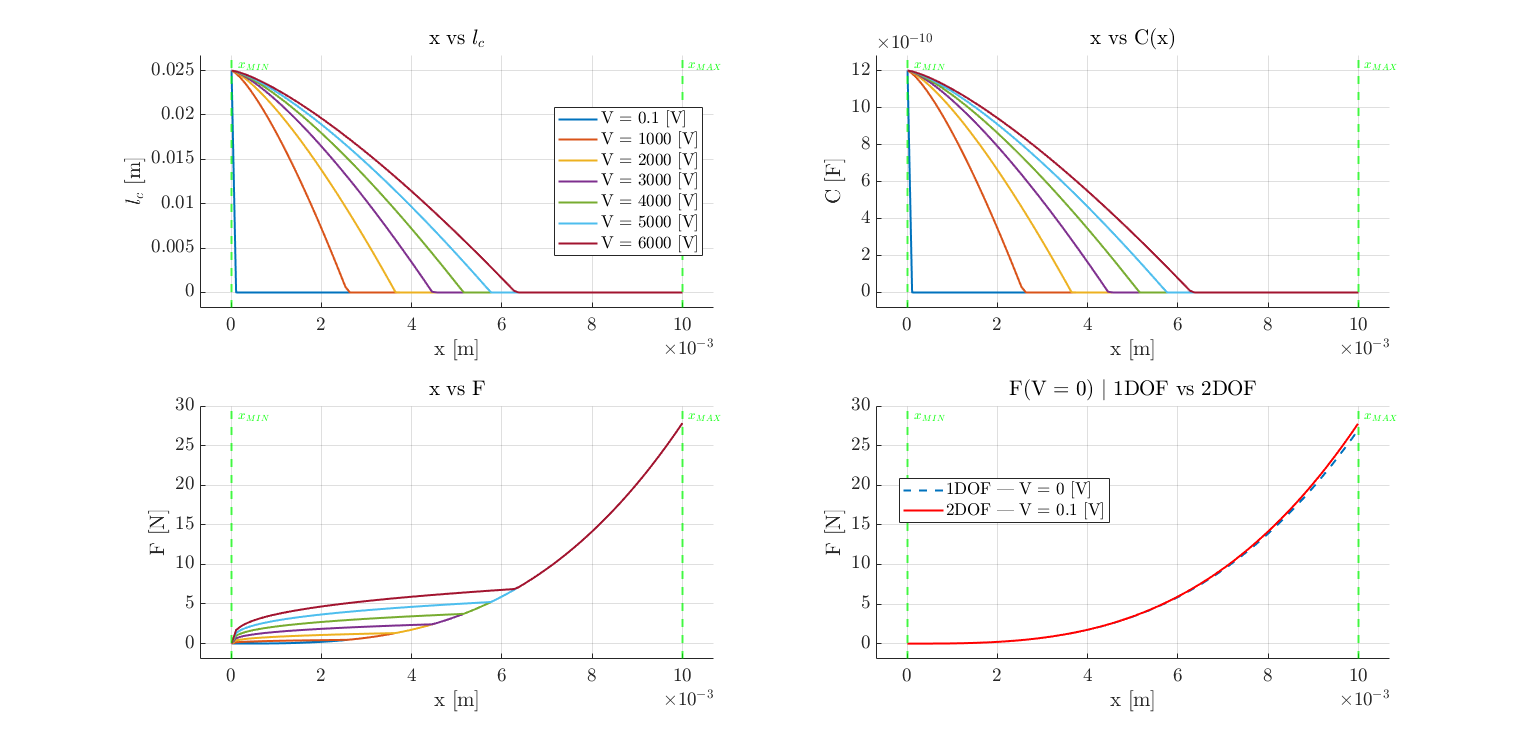

subplot(2,2,1); hold on
for i = 1:2:length(V_range) 
    % fplot(int_lc(x,V_range(i)), [x_range(1), x_range(end)], plcol(i), 'DisplayName', ['V = '  num2str(V_range(i))  ' [V]'])
    plot(x_range, sol_lc(i,:), 'DisplayName', ['V = '  num2str(V_range(i))  ' [V]'])
end
plot_xminmax(x_range(1), x_range(end))
addlabels("x [m]", "$l_c$ [m]", "x vs $l_c$")
legend('Location','east');
xlim("padded"); ylim("padded")

subplot(2,2,2); hold on
for i = 1:2:length(V_range)    
    % plot(x_range_ref, int_C1{i}, plcol(i), 'DisplayName', ['V = '  num2str(V_range(i))  ' [V]'])
    plot(x_range, sol_C1(i,:), 'DisplayName', ['V = '  num2str(V_range(i))  ' [V]'])
end
plot_xminmax(x_range(1), x_range(end))
addlabels("x [m]", "C [F]", "x vs C(x)")
xlim("padded"); ylim("padded")

subplot(2,2,3); hold on
for i = 1:2:length(V_range)  
    % plot(x_range_ref, int_F{i}, plcol(i), 'DisplayName', ['V = '  num2str(V_range(i))  ' [V]'])
    plot(x_range, sol_F(i,:), 'DisplayName', ['V = '  num2str(V_range(i))  ' [V]'])
end
plot_xminmax(x_range(1), x_range(end))
addlabels("x [m]", "F [N]", "x vs F")
xlim("padded"); ylim("padded")

subplot(2,2,4); hold on
plot(x_range_ref, subs(sdata1(pstrain_1dof.FVmin, "PSTRAIN"), x, x_range_ref), '--', 'DisplayName', '1DOF | V = 0 [V]') 
plot(x_range_ref, int_F(x_range_ref, V_range(1)), plcol(1), 'DisplayName', ['2DOF | V = ' num2str(V_range(1)) ' [V]']) 
plot_xminmax(x_range(1), x_range(end))
addlabels("x [m]", "F [N]", "F(V = 0) $\vert$ 1DOF vs 2DOF")
legend('Location', 'best')
xlim("padded"); ylim("padded")

% myfig(2,'V - l_c'); 
% idx = 1;
% for i = floor(linspace(1, length(x_range), 8))
%     if mod(idx,2) == 0
%         st = '--';
%     else
%         st = '-';
%     end
%     % plot(res_2dof_pstrain{end}.V_range, sol_lcV{i})
%     plot(V_rangeref, int_lcV{i}, st, 'DisplayName', ['x = ' num2str(x_range(i), '%.3e')])
%     idx = idx + 1;
% end
% addlabels("V [V]", "$l_c$ [m]", "V vs $l_c$")
% legend('Location', 'best')
step = floor(length(x_range) / 8);
myfig(2, "")

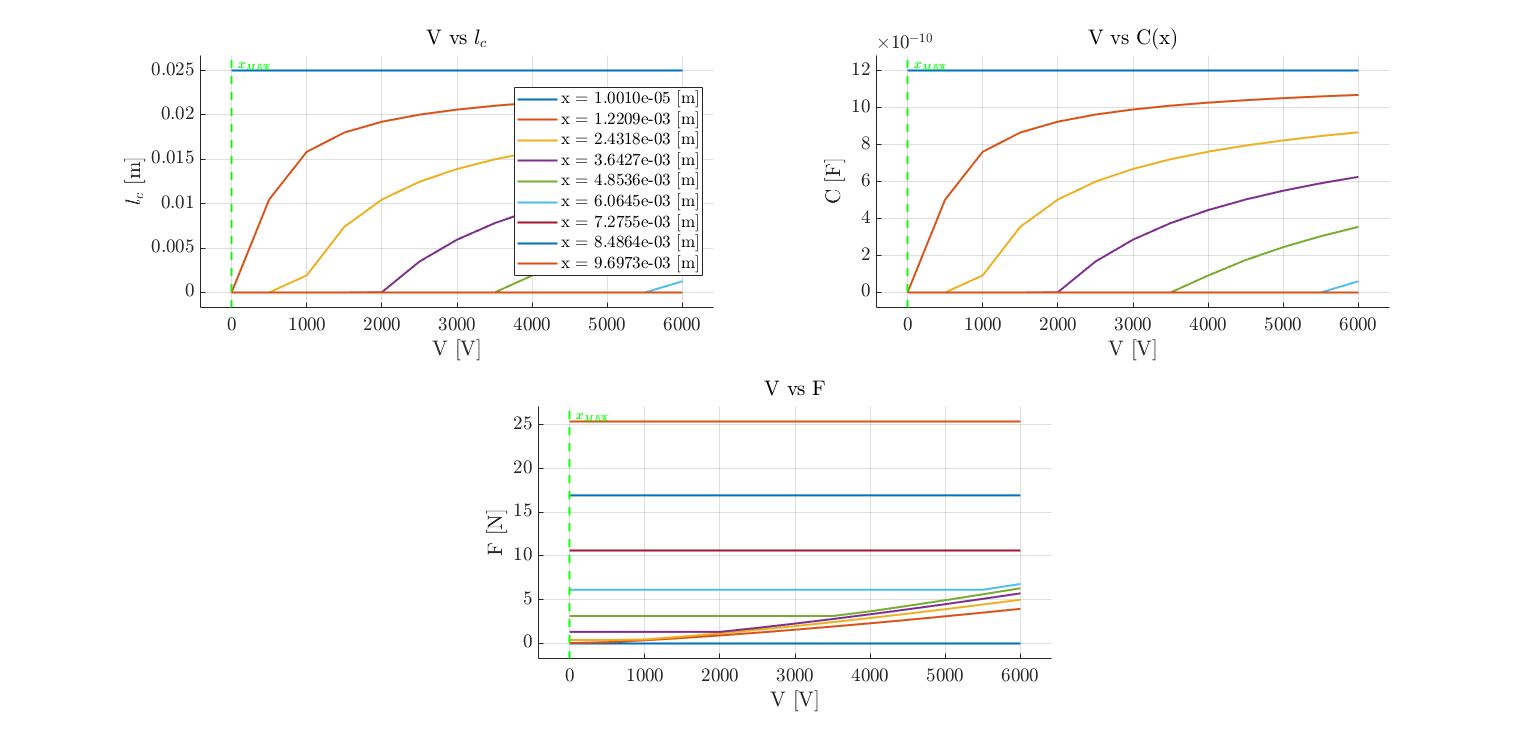

subplot(2,2,1); hold on
for i = 1:step:length(x_range) 
    plot(V_range, int_lc(x_range(i),V_range), 'DisplayName', ['x = '  num2str(x_range(i), '%.4e')  ' [m]'])
    
end
plot_xminmax(x_range(1), x_range(end))
addlabels("V [V]", "$l_c$ [m]", "V vs $l_c$")
legend('Location','east');
xlim("padded"); ylim("padded")

subplot(2,2,2); hold on
for i = 1:step:length(x_range)    
    plot(V_range, int_C1(x_range(i),V_range), 'DisplayName', ['x = '  num2str(x_range(i), '%.4e')  ' [m]'])
end
plot_xminmax(x_range(1), x_range(end))
addlabels("V [V]", "C [F]", "V vs C(x)")
xlim("padded"); ylim("padded")

subplot(2,2,3.5); hold on
for i = 1:step:length(x_range)  
    plot(V_range, int_F(x_range(i),V_range), 'DisplayName', ['x = '  num2str(x_range(i), '%.4e')  ' [m]'])
end
plot_xminmax(x_range(1), x_range(end))
addlabels("V [V]", "F [N]", "V vs F")
xlim("padded"); ylim("padded")

## Elastic energy from x - F, varying x_max

Uel_xmax = zeros(length(x_range_ref),1);
uel_xmax = zeros(length(x_range_ref),1);
Voltmp = sdata2(Vol);

for i = 1:length(x_range_ref)
    Uel_xmax(i) = trapz(x_range_ref(1:i), int_F(x_range_ref(1:i), V_range(end)),2) - trapz(x_range_ref(1:i), int_F(x_range_ref(1:i), V_range(1)),2);
    uel_xmax(i) = Uel_xmax(i) / double(subs(Voltmp, {x, l_c}, {x_range_ref(i), int_lc(x_range_ref(i), V_range(end))}));
end

xr = res_1dof_pstrain.x_range_eff;
% pureUel = sdata2(1/2 * sigma_1(x) * epsilon_1(x) * Vol, "PSTRAIN", 'except', {x, l_c});
% pureUel = double(subs(pureUel, {x, l_c}, {x_range_ref(end), int_lc{1}(end)}));

myfig(3, "U_{el} and u_{el}");

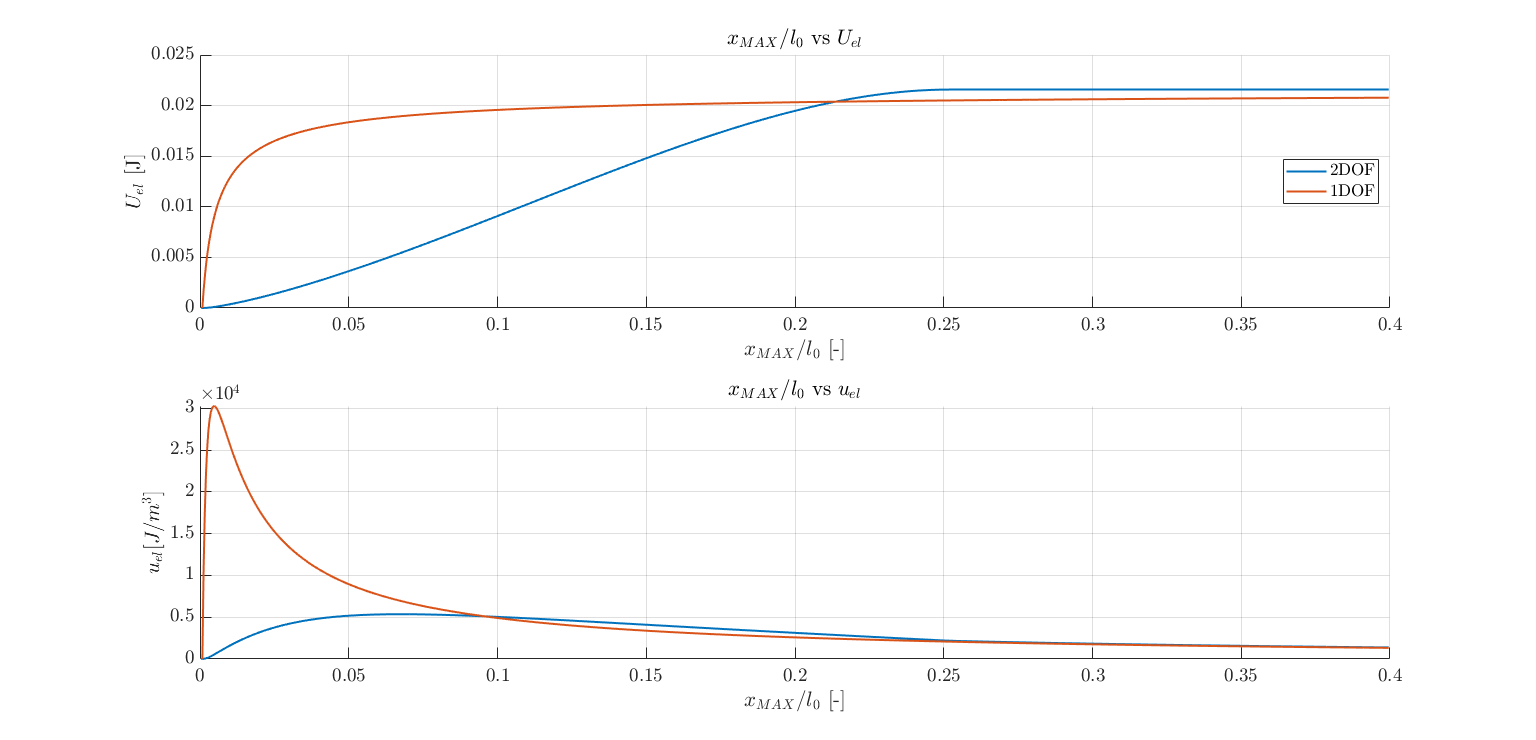

subplot(2,1,1); hold on
plot(x_range_ref / sdata2(l_0), Uel_xmax, 'DisplayName', '2DOF')
% plot(x_range_ref / sdata2(l_0), pureUel * ones(length(x_range_ref), 1), 'DisplayName', 'Pure $U_{el}$ (Max def.) 2DOF')
plot(xr / sdata2(l_0), res_1dof_pstrain.Uel_xmax, 'DisplayName', '1DOF')
addlabels("$x_{MAX} / l_0$ [-]", "$U_{el}$ [J]", "$x_{MAX} / l_0$ vs $U_{el}$")
legend("Location", "east")

subplot(2,1,2); hold on
plot(x_range_ref / sdata2(l_0), uel_xmax, 'LineWidth', 1.5)
plot(xr / sdata2(l_0), res_1dof_pstrain.uel_xmax)
addlabels("$x_{MAX} / l_0$ [-]", "$u_{el} [J/m^3]$", "$x_{MAX} / l_0$ vs $u_{el}$")

res_2dof_pstrain.sol_lc = sol_lc;
res_2dof_pstrain.sol_F = sol_F;
res_2dof_pstrain.sol_C1 = sol_C1;
res_2dof_pstrain.int_lc = int_lc;
res_2dof_pstrain.int_F = int_F;
res_2dof_pstrain.int_C1 = int_C1;
res_2dof_pstrain.x_range = x_range;
res_2dof_pstrain.x_range_ref = x_range_ref;
res_2dof_pstrain.V_range = V_range;
res_2dof_pstrain.Uel_xmax = Uel_xmax;
res_2dof_pstrain.uel_xmax = uel_xmax

res_2dof_pstrain = struct with fields:
         sol_lc: [13×100 double]
          sol_F: [13×100 double]
         sol_C1: [13×100 double]
         int_lc: @(x,V)interp2(X,Y,sol_lc,x,V)
          int_F: @(x,V)interp2(X,Y,sol_F,x,V)
         int_C1: @(x,V)interp2(X,Y,sol_C1,x,V)
        x_range: [100×1 double]
    x_range_ref: [1.001000000000000e-05 2.001000000000000e-05 3.001000000000000e-05 4.001000000000000e-05 5.001000000000000e-05 6.001000000000000e-05 7.001000000000000e-05 8.001000000000000e-05 9.001000000000000e-05 … ] (1×999 double)
        V_range: [0.100000000000000 500 1000 1500 2000 2500 3000 3500 4000 4500 5000 5500 6000]
       Uel_xmax: [999×1 double]
       uel_xmax: [999×1 double]



save("2DOF\res_2dof_pstrain.mat", "res_2dof_pstrain")

## Solve full capacitance

% eq_diffx = diff(Uel, x) - V^2 /2 * diff(C1+C2, x) == F;
% eq_difflc = diff(Uel,l_c) - V^2 /2 * diff(C1+C2, l_c) == 0;
% eq_x = sdata2(eq_diffx);
% eq_lc = sdata2(eq_difflc);
% 

% x_range = double(linspace(x_min+1e-6, 10e-3, 20))';
% V_range = [0 1000:1000:6000];
% sol_lc = cell(1, length(V_range));
% sol_F = cell(1, length(V_range));
% sol_C = cell(1, length(V_range));  
% tic 
% for i = 1:length(V_range)
%     eq_lc_tmp = subs(eq_lc, V, V_range(i));
%     s_tmp = double(sdata2(l_0));
%     for j = 1:length(x_range)
%         s = double(vpasolve(subs(eq_lc_tmp, x, x_range(j))));
%         % s(imag(s) == 0 & s <= sdata2(l_0))
%         if s(1) <= 0 && isreal(s(1))
%             s(1) = 1e-7;
%         end
%         sol_lc{i}(j) = s(1);
%         sol_F{i}(j) = double(lhs(subs(eq_x, {V, l_c, x}, {V_range(i), sol_lc{i}(j), x_range(j)})));
%         sol_C{i}(j) = double(subs(sdata2(C1), {V, l_c, x}, {V_range(i), sol_lc{i}(j), x_range(j)}));    
%     end
% end
% toc



% sol_C2 = cell(1, length(V_range));
% sol_C = cell(1, length(V_range));
% tmpC2 = sdata2(C2);
% for i = 1:length(V_range)
%     for j = 1:length(x_range)
%         sol_C2{i}(j) = double(subs(tmpC2, {x, l_c}, {x_range(j), sol_lc{i}(j)}));
%         sol_C{i}(j) = sol_C1{i}(j) + sol_C2{i}(j);
%     end
% end
% myfig(2,""); hold on
% for i = 1:length(V_range)
%     plot(x_range, sol_C1{i}, plcol(i), 'LineWidth', 1.5,'DisplayName', ['V = '  num2str(V_range(i))  ' [V]'])
%     plot(x_range, sol_C{i}, plcol(i,'--'), 'LineWidth', 1.5,'DisplayName', ['V = '  num2str(V_range(i))  ' [V]'])
% end
% plot_xminmax(x_range(1), x_range(end))
% addlabels("x [m]", "C [F]", "x vs C(x)")
% xlim("padded"); ylim("padded")




















